# Fourier Series Lab

 **Question 1. **Consider the Fourier sine series:


$$f(t) = \sum_{n=1}^\infty b_n \sin \left(  2 \pi    t \right)$$


Adjust the coefficients for the sine basis in the [Sine and Cosine Series app](matlab: SinCosSeries) to determine the values of the coefficients $b_2$ and $b_4$ (approximately) that generate the function $f$ pictured below. The other coefficients are zero.

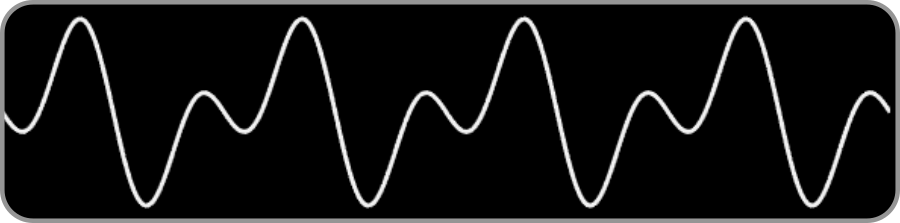

% Replace the NaNs with your answers
Q1_b2 = 1;
Q1_b4 = -1;

Questions 2 and 3 use data from an audio signal. Run this section to load the data and compute its Fourier series coefficients.

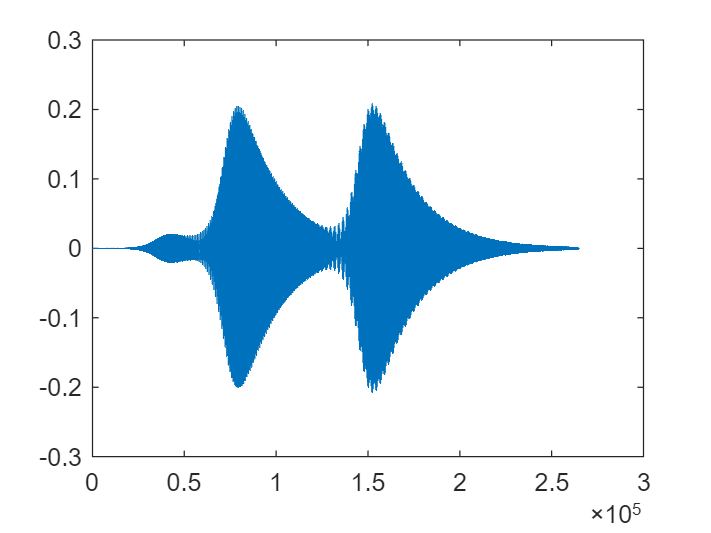

[y,Fs] = audioread("SynthesizedSound.mp4");
sound(y,Fs)
plot(y)

% [freq,a,b] = computeFourierCoef(y,Fs);

**Question 2. **Compute the magnitude and phase of the Fourier coefficients which are stored in the vectors `a` and `b`. Store the results in `A` and `phi`.

**Hint:** Use  [`atan2`](https://www.mathworks.com/help/matlab/ref/atan2.html) to compute the phase.

% Replace the NaNs with your answers
A = sqrt(a.^2 + b.^2);

Operator '.^' is not supported for operands of type 'cell'.

phi = atan2(b,a);

**Question 3. **Plot the magnitude vector `A` against the frequency vector `freq`.

function [freq,a,b] = computeFourierCoef(y,Fs)
    Nmodes = 1000;
    yc = y;
    
    tc = 1/Fs*(0:(length(yc)-1));
    L = tc(end)/2; % The domain is assumed to be 2L
    freq = (1:Nmodes)/(2*L); % Frequencies

    % Estimate coefficients using trapezoid rule
    a = zeros(1,Nmodes);
    b = zeros(1,Nmodes);
    a0 = 1/L*trapz(tc,yc);
    for n = 1:Nmodes
        a(n) = 1/L*trapz(tc,cos(n*pi/L*tc).*yc);
        b(n) = 1/L*trapz(tc,sin(n*pi/L*tc).*yc);
    end
end
